# Deep Learning mit MATLAB

% Die MATLAB Deep LEarning Toolbox stellt einige Funktionen zum Arbeiten mit Tiefen NEuronalen Netzen zur Verfügung.
% Stellen Sie sicher, das der Arbeitspfad richtig eingestellt ist, da sonst
% die Bilder nicht gefunden werden kann. 

filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(filename)


## Daten Laden und Data Store erstellen

filename = filename + "\Trainingsdaten\AusgeschnittenFürTraining\TrainingsdatenSatz30Schild1";
imdsSchilder = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Explorative Datenanalyse

% numImgs = length(imdsZahlen.Files)
countEachLabel(imdsSchilder)

ans = 2×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder               3018 
    Geschwindigkeitsbegrenzung_30     337 


%genau gleiche viele einträge von jedem Label
numPerLabel =min(countEachLabel(imdsSchilder).Count)

numPerLabel = 337

% Labels extrahieren
allLabels = unique(imdsSchilder.Labels);
balancedFiles = [];

for i = 1:numel(allLabels)
    label = allLabels(i);
    % Alle Bilder mit diesem Label holen
    idx = find(imdsSchilder.Labels == label);
    % Wenn mehr als numPerLabel vorhanden, zufällig auswählen
    if numel(idx) >= numPerLabel
        selectedIdx = randsample(idx, numPerLabel);
        balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
    else
        warning("Label '%s' hat weniger als %d Bilder.", label, numPerLabel);
    end
end

% Neuen ImageDatastore mit ausgewählten Dateien erstellen
balancedDS = imageDatastore(balancedFiles, 'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
    fullfile(filename, '\'), filesep))));

% img = read(imdsZahlen);
% figure;
% imshow(img)
% img = readimage(imdsZahlen, 1650);
% figure;
% imshow(img)
% size(img)


## Erzeuge Trainings- und Validierungsdatensatz

[imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");

filename = filename + "\BilderOhneSchilder";
imdsSchilder2 = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Defeniere Netzwerkschichten

% Einfaches CNN definieren

layers = [
    imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")
    convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
    reluLayer("Name", "relu_1")
    maxPooling2dLayer(2, 'Stride', 2,"Name", "maxpool_1")
    convolution2dLayer(3, 16, 'Padding', 'same',"Name", "conv_2")
    reluLayer("Name", "relu_2")
    maxPooling2dLayer(2, 'Stride', 2,  "Name", "maxpool_2")
    fullyConnectedLayer(2, "Name", "fc") 
    softmaxLayer("Name", "softmax")
    classificationLayer("Name", "output")
];


% %komplexes modell
% layers = [
%     imageInputLayer([200 200 3], "Name", "imageinput")
%     convolution2dLayer([3 3], 32, "Name", "conv", "Padding", "same")
%     reluLayer("Name", "relu")
%     maxPooling2dLayer([5 5], "Name", "maxpool", "Padding", "same")
%     fullyConnectedLayer(2, "Name", "fc")
%     softmaxLayer("Name", "softmax")
%     classificationLayer("Name", "classoutput")];


## Exploration des Netzwerkes

% layers(1).Name
% layers(1). InputSize
% layers(end-2).OutputSize

## Anpassen Hyperparameter

%sicherstellen das alle Bilder die gleiche größe haebn
augTrain  = augmentedImageDatastore([48 48 3], imdsTrain, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
aug2= augmentedImageDatastore([48 48 3], imdsSchilder2, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
% Trainingsparameter Schlake
% opts = trainingOptions("adam", "ValidationData", augVal, "Shuffle", "every-epoch", "Plots", "training-progress","InitialLearnRate",0.01);
% Trainingsparameter 
options = trainingOptions('adam', ...
 'MaxEpochs', 10, ...
 "InitialLearnRate", 0.001, ...
    'MiniBatchSize', 16, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');

## Training

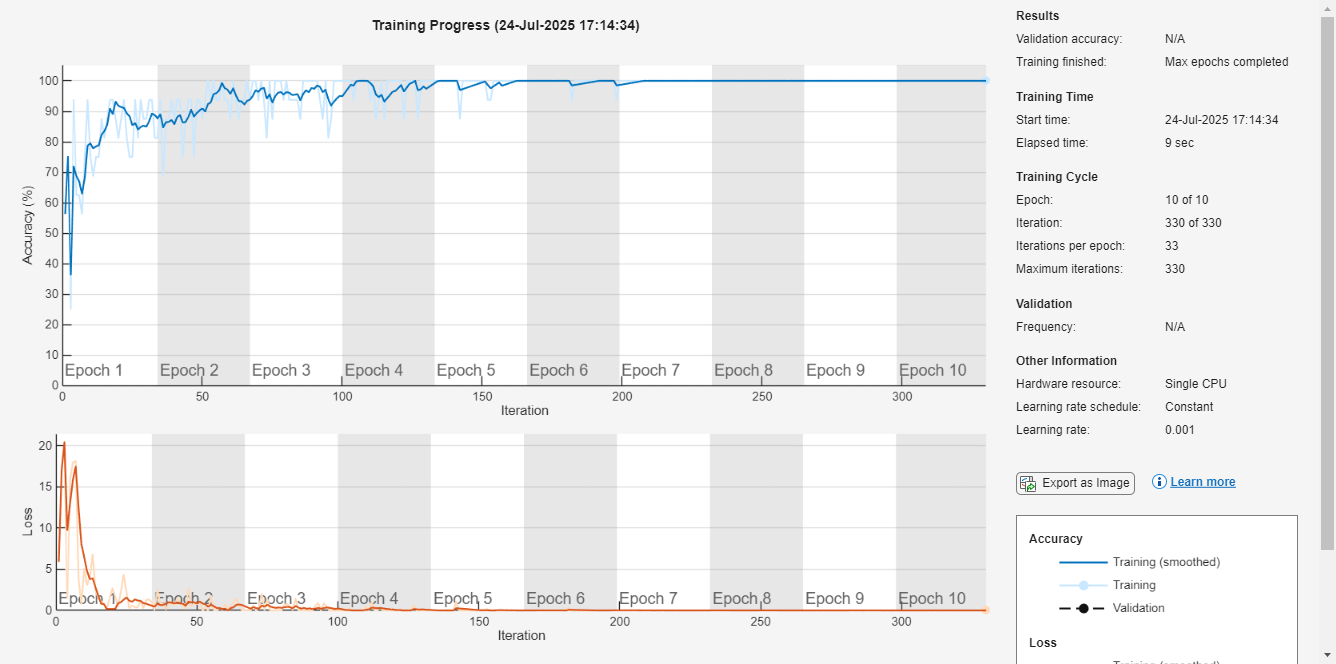

net = trainNetwork(augTrain, layers, options);

## Schätzung

% Testen des Neuronalen Netzes
trainPreds = classify(net,augTrain);
testPreds = classify(net,augVal);
testpreds2 = classify(net,aug2);

## **Falsche Ergebnisse ausgeben**

%Falsch erkantte Bilder anzeigen
trueLabelsTrain = imdsTrain.Labels;
trueLabelsVali = imdsValidation.Labels;
trueLabelsVali2 = imdsSchilder2.Labels;

wrongIdxtrain = find(trainPreds ~= trueLabelsTrain);
wrongIdxVali = find(testPreds ~= trueLabelsVali);
wrongIdxVali2 = find(testpreds2 ~= trueLabelsVali2);


% for i = 1:length(wrongIdxtrain)
%     img = readimage(imdsTrain, wrongIdxtrain(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(trainPreds(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
% end

% for i = 1:length(wrongIdxVali)
%     img = readimage(imdsValidation, wrongIdxVali(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(testPreds(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
% end

dateiname = imdsSchilder2.Files(wrongIdxVali2);
% for i = 1:length(wrongIdxVali2)
%     img = readimage(imdsSchilder2, wrongIdxVali2(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(testpreds2(wrongIdxVali2(i))), string(trueLabelsVali2(wrongIdxVali2(i)))));
% end

## Evaluierung

% Evaluierung des Modelles
confMat = confusionmat(imdsTrain.Labels, trainPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 100.00%


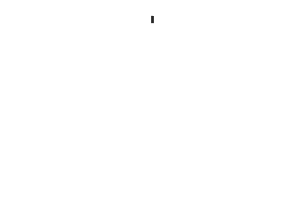

confusionchart(imdsTrain.Labels, trainPreds);

confMat = confusionmat(imdsValidation.Labels, testPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 97.01%


confusionchart(imdsValidation.Labels, testPreds);